# ELABORATO 2 -  PRODOTTO MATRICE VETTORE PER RIGHE

# LO BRUTTO FABIO / MAIONE PAOLO

## DEFINIZIONE DEL PROBLEMA

Si vuole progettare un algoritmo in MPI per risolvere il prodotto vettoriale tra una matrice, di dimensioni M*N, e un vettore di reali, di dimensione N, su p processori.

In particolare si utilizza l'infrastruttura S.C.o.P.E. per permettere l'esecuzione del software in un ambiente parallelo.

## DESCRIZIONE DELL'ALGORITMO

In particolare le fasi dell'algoritmo, implementato nel file `elaborato_2.c`, sono:

1) Distribuzione per righe della matrice in p processori e distribuzione del vettore: ognuno dei p processori eseguirà il prodotto vettoriale tra la porzione di matrice ricevuta dal processo *root (*cioè quello con rank 0), e il vettore;

2) Elaborazione del prodotto vettoriale in parallelo ;

3) Aggregazione del vettore calcolata nel processo *root* che determinerà il risultato finale.

A tal proposito sono state utilizzate le primitive fornite da MPI (rispettivamente per la prima fase `MPI_Scatterv()` e per la terza `MPI_Gatherv()`).

Inoltre l'algoritmo progettato comprende anche il caso in cui la dimensione M (cioè il numero di righe della matrice) non sia multipla del numero di processori p a disposizione.

Si è scelto di misurare i tempi di esecuzione nel processo di rank 0 usando la primitiva` MPI_Wtime()` tra la fase 2 e la fase 3 scegliendo il minimo tra 3 misurazioni ripetute.

Infine, si osservi che i controlli di robustezza del software sono stati interamente delegati al processo *root*.

## INPUT, OUTPUT E CONDIZIONI DI ERRORE

- **Input**: la matrice e il vettore di cui effettuare il prodotto vettoriale, le loro dimensioni `M`, `N` e `dim_vett`.

- **Output**: il vettore risultato dell prodotto vettoriale tra la matrice e il vettore.

- **Condizioni di errore**: la dimensione delle righe della matrice deve essere uguale al numero di colonne del vettore e devono essere interi positivi. Il numero di righe della matrice non deve essere minore del numero di processori.

## ESEMPIO DI FUNZIONAMENTO

Nell'immagine seguente vi è un esempio di funzionamento, con 4 processori, matrice di dimensione 7x8 e dimensione del vettore pari a 7 .

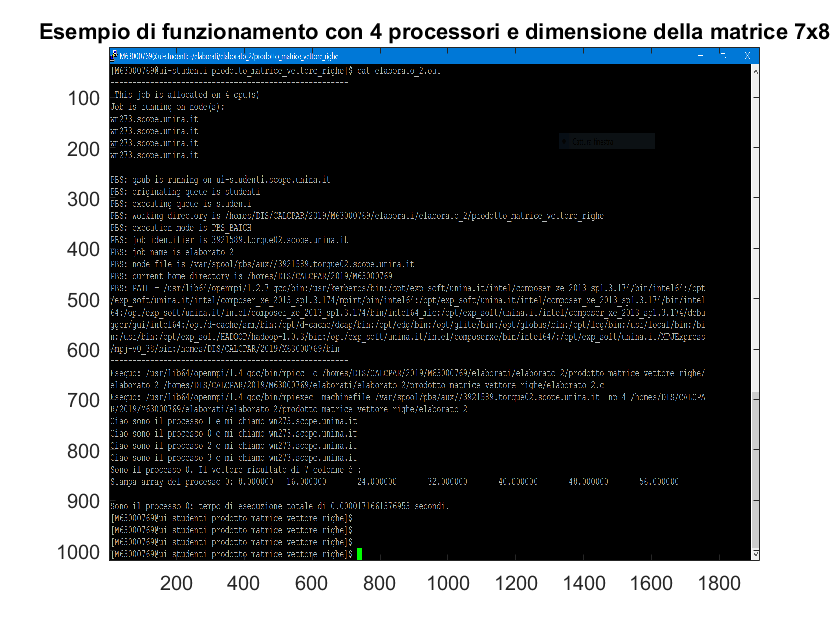

%esempio di funzionamento
funzionamento

## ESEMPI DI ERRORE

Nelle successivi immagini, invece, sono mostrati i messaggi di errore al verificarsi delle condizioni sopra citate.

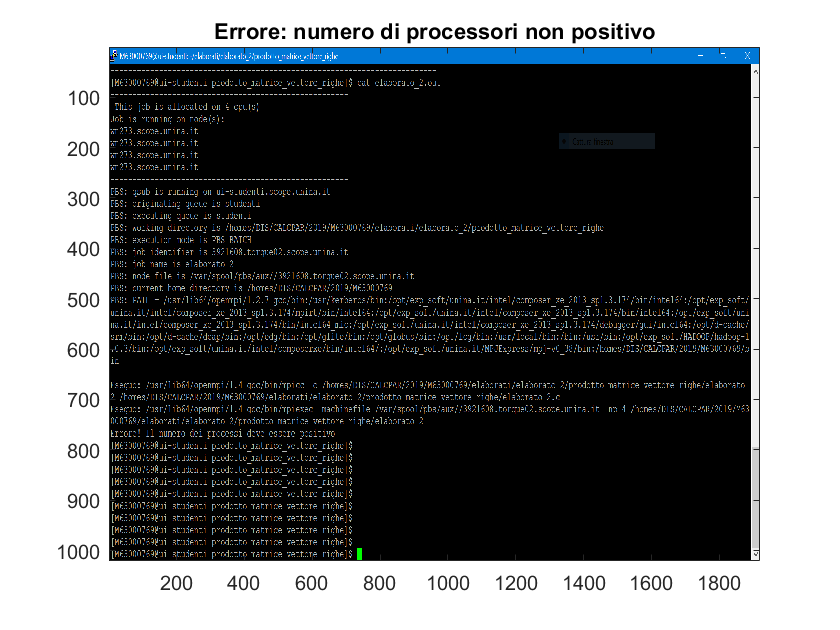

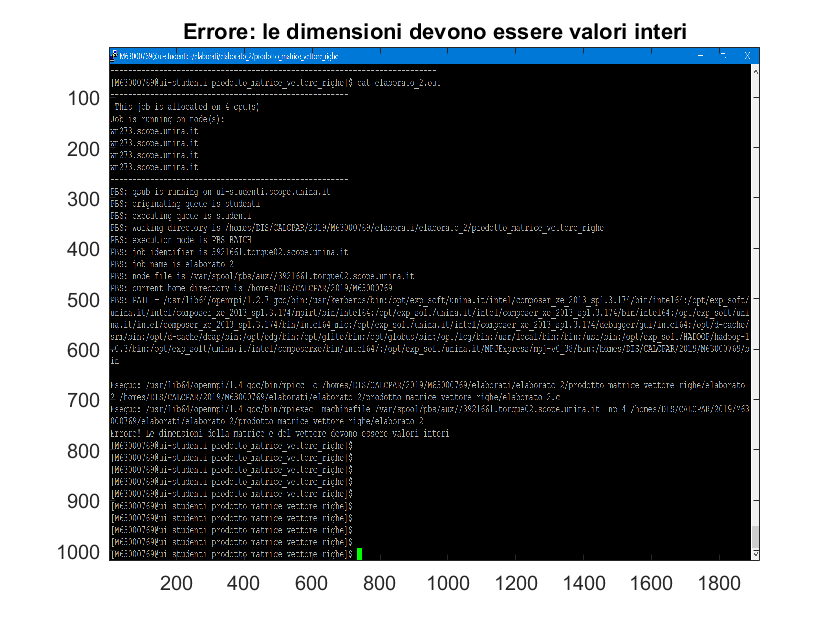

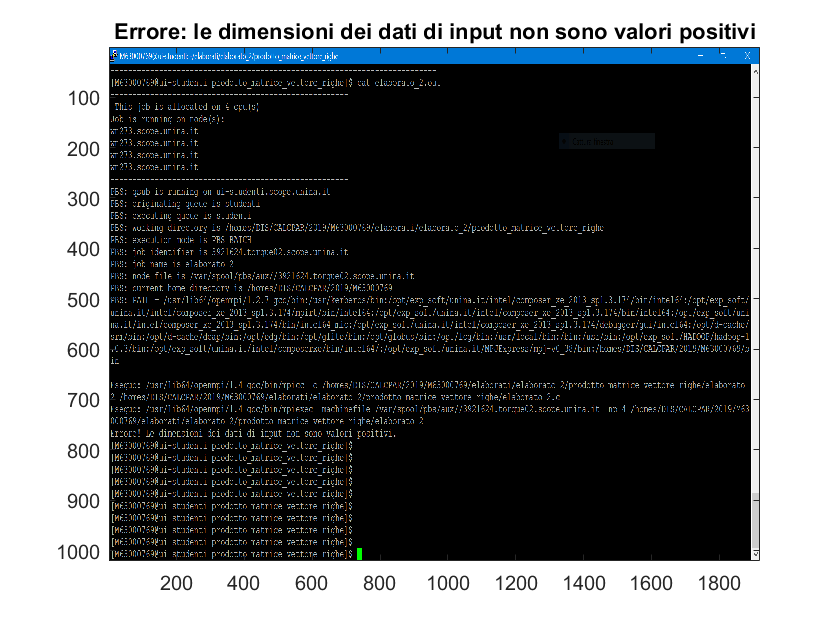

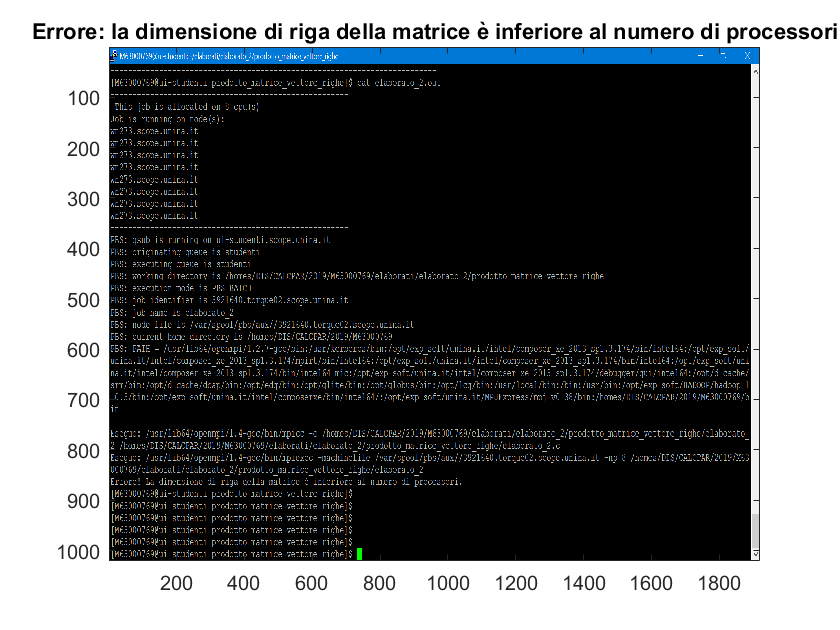

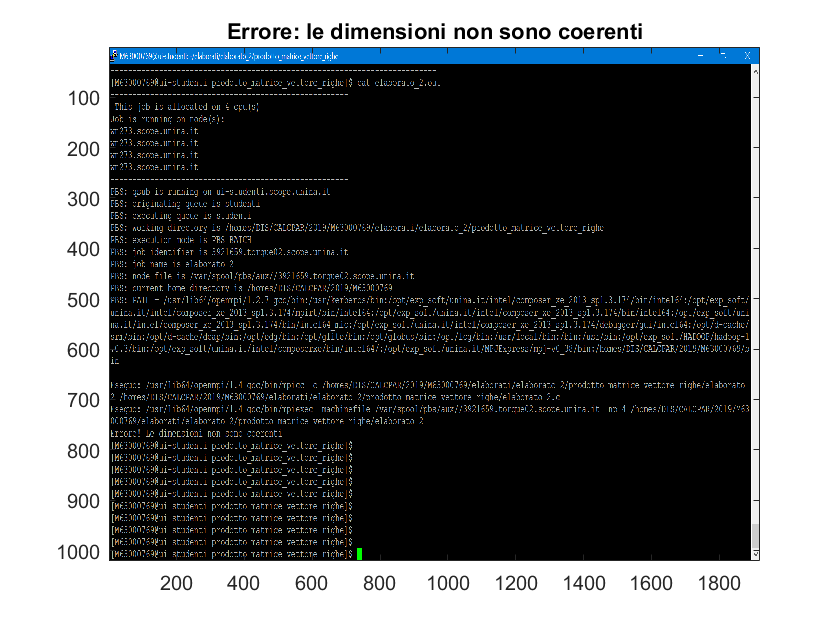

%un esempio per ciascuna condizione di errore
errori

## ANALISI DELLE PRESTAZIONI (T(p), S(p), E(p))

## Tempo di esecuzione - T(p)

Si è scelto di misurare i tempi di esecuzione nel processo* root* usando la primitiva `MPI_Wtime()`. In particolare l'intervallo di tempo misurato è quello che comprende le fasi 2 e 3 dell'algoritmo prima citate.

Si è scelto inoltre di considerare tre casi diversi che rappresentano le tre possibilità per le dimensioni della matrice: il caso in cui il numero di righe è maggiore numero di colonne, il caso in cui il numero di righe è minore del numero di colonne ed, infine, il caso in cui la matrice è quadrata.

Per ciascuna misurazione corrispondente ai tre casi

- se il numero di righe M è maggiore del numero di colonne N si fa variare M da 5000 a 50000 con N fissato a 1000

- se il numero di righe M è minore del numero di colonne N si fa variare N da 5000 a 50000 con M fissato a 1000

- se la matrice è quadrata si fa variare M=N da 100 a 10000

è stato considerato il minimo tra 3 esecuzioni ripetute, eseguite in momenti diversi.

Si noti che nel caso di matrici quadrate si è scelta una diversa configurazione rispetto al caso di matrici sbilanciate data l'impossibilità di eseguire sul cluster il programma con dimensioni 50000 x 50000. Pertanto è parso ragionevole, solo nel caso di matrici quadrate, ridurre la dimensione massima.

I grafici e le tabelle riassumono i risultati ottenuti per tutti i possibili valori di M,N e p.

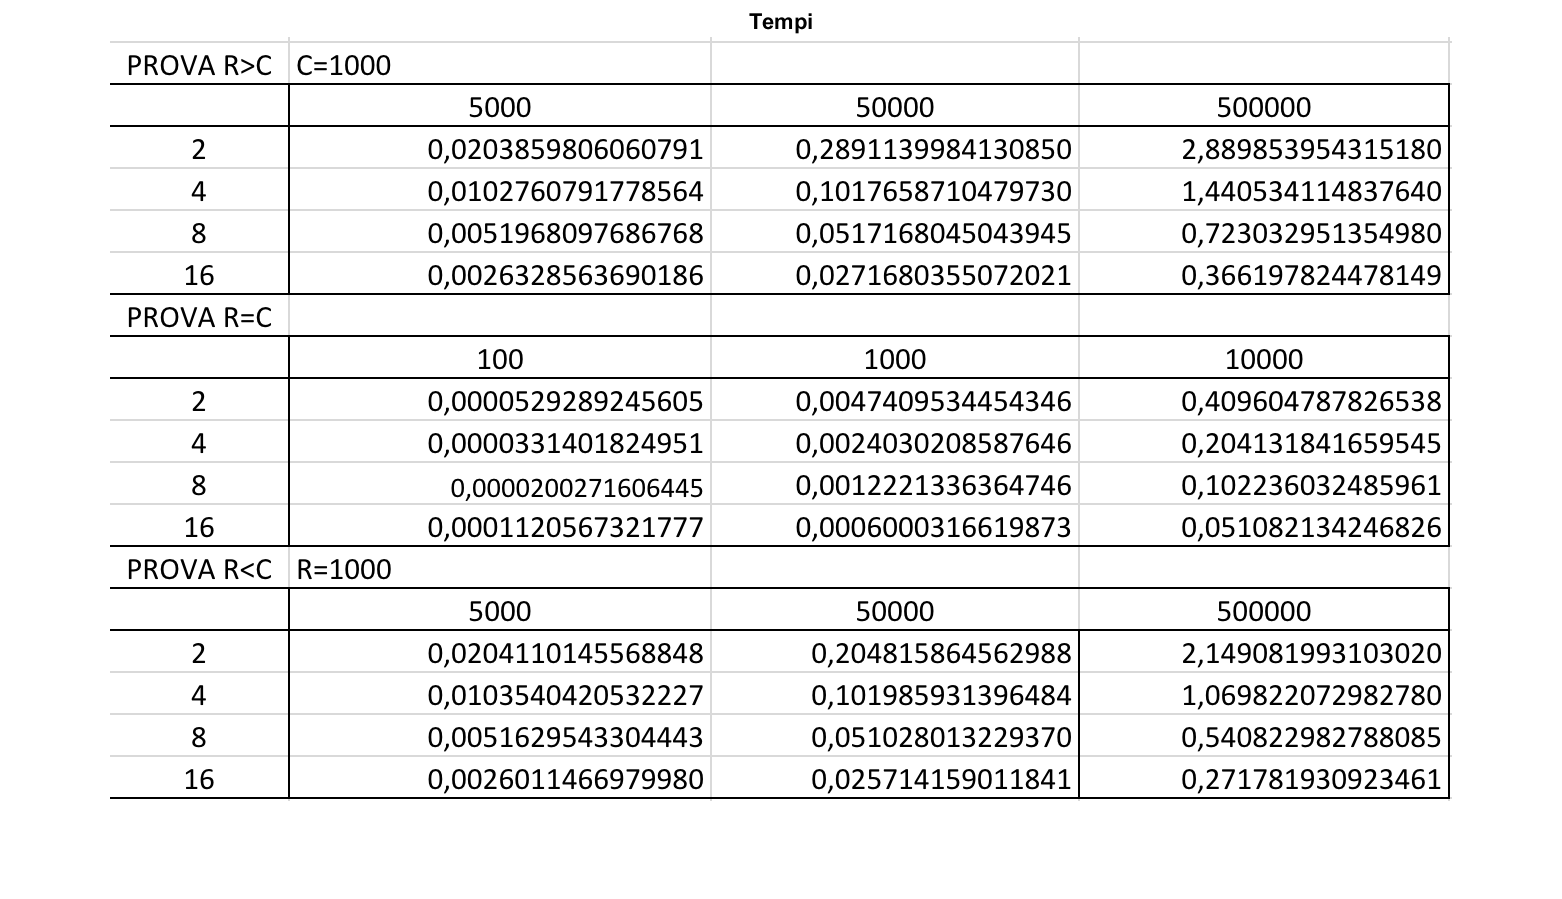

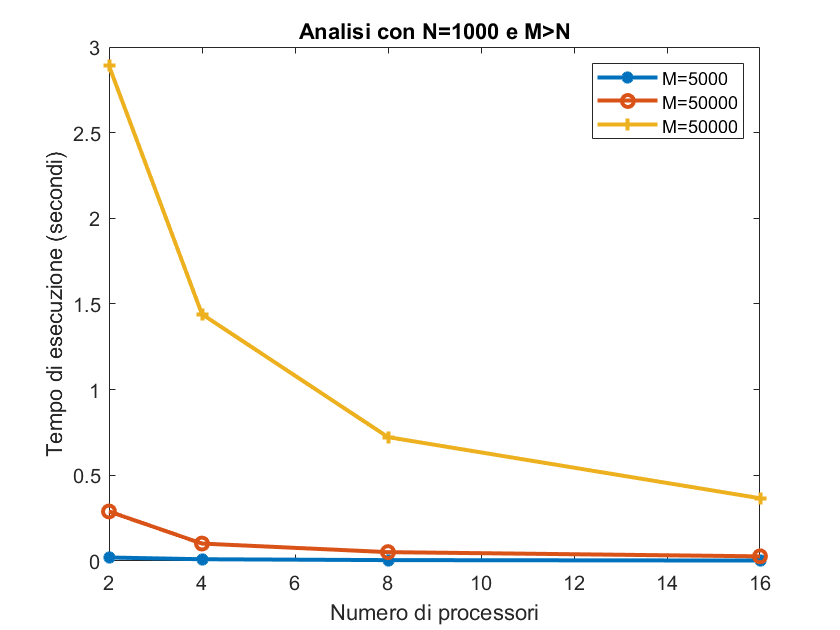

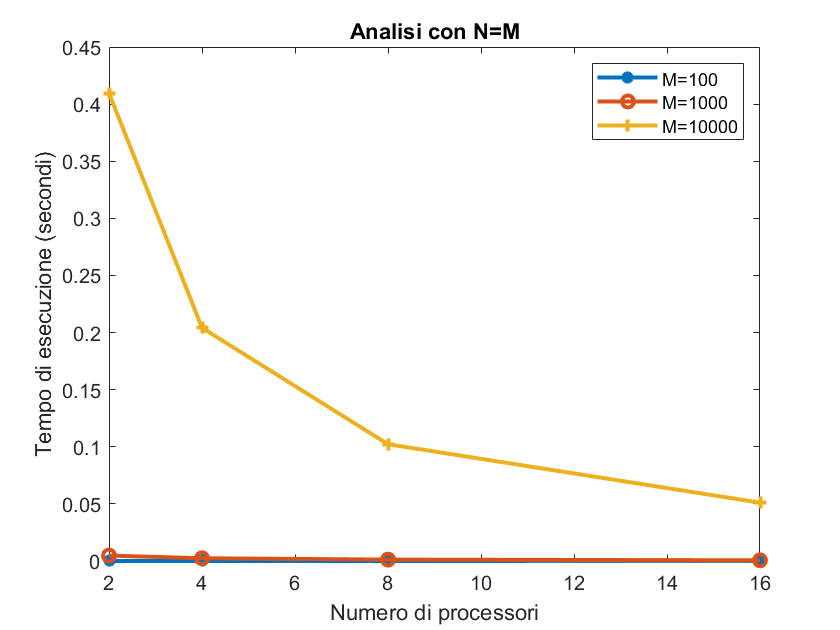

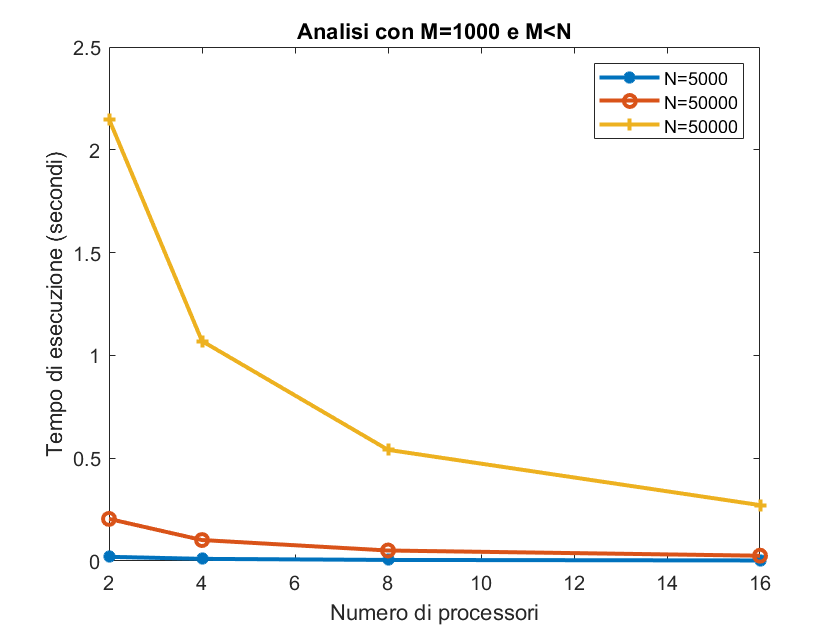

%esecuzione script per tabelle e grafici
tempi

Per considerazioni più di dettaglio su questi risultati si rimanda alla sezione Conclusioni.

## Speed up ed Efficienza - S(p) ed E(p)

Si è calcolato, inoltre, il tempo di riferimento T(1) che corrisponde al tempo di esecuzione su un unico processore.

A partire dai tempi misurati nella sezione precedente e da T(1) è stato calcolato lo speed-up al variare di M, N e p.

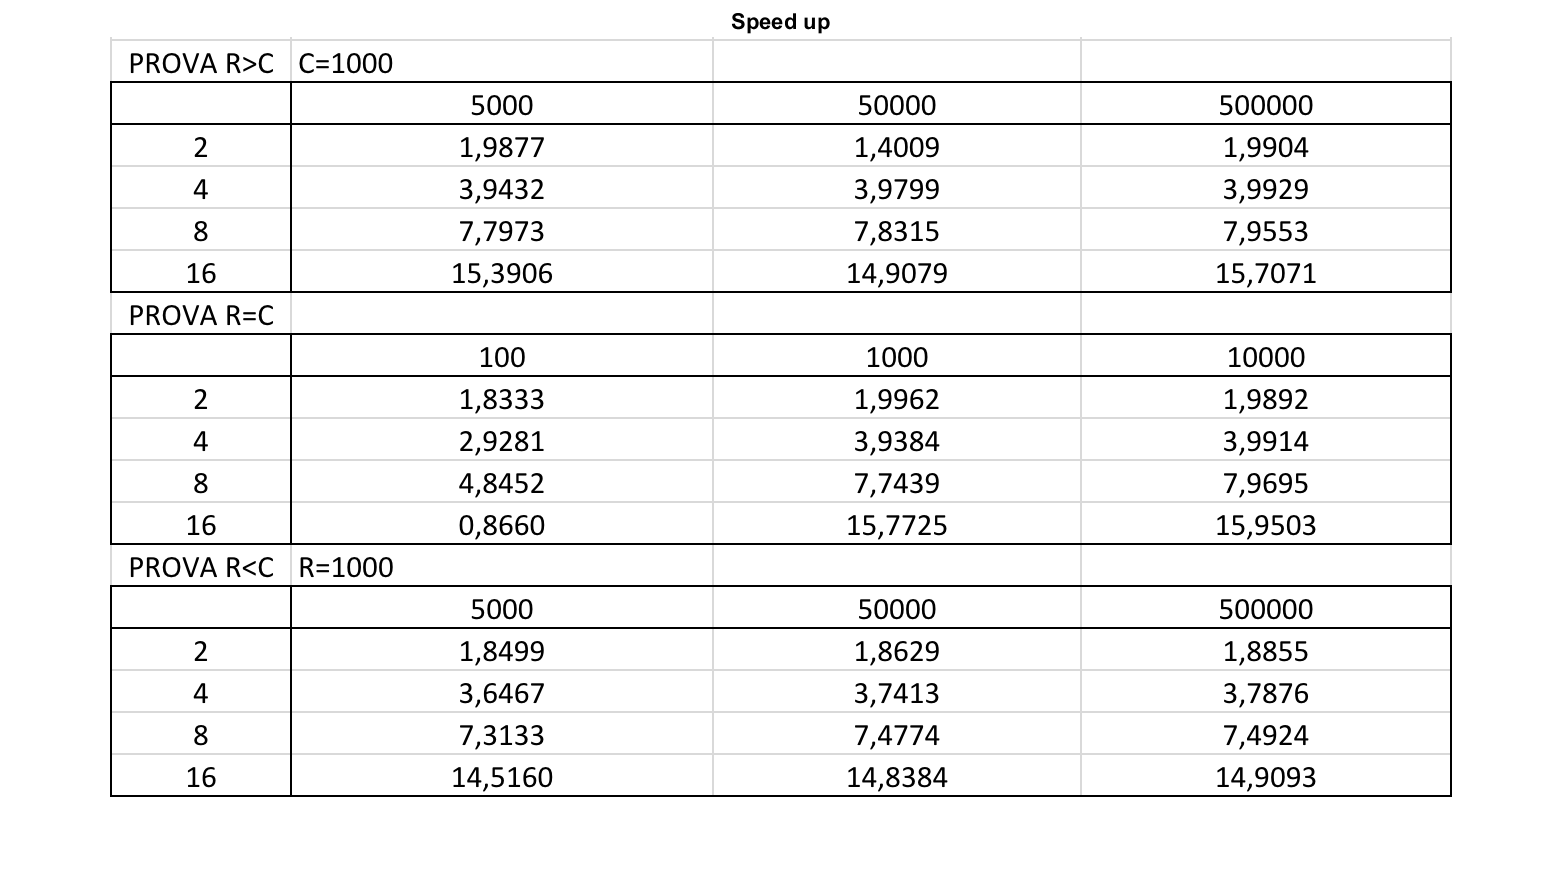

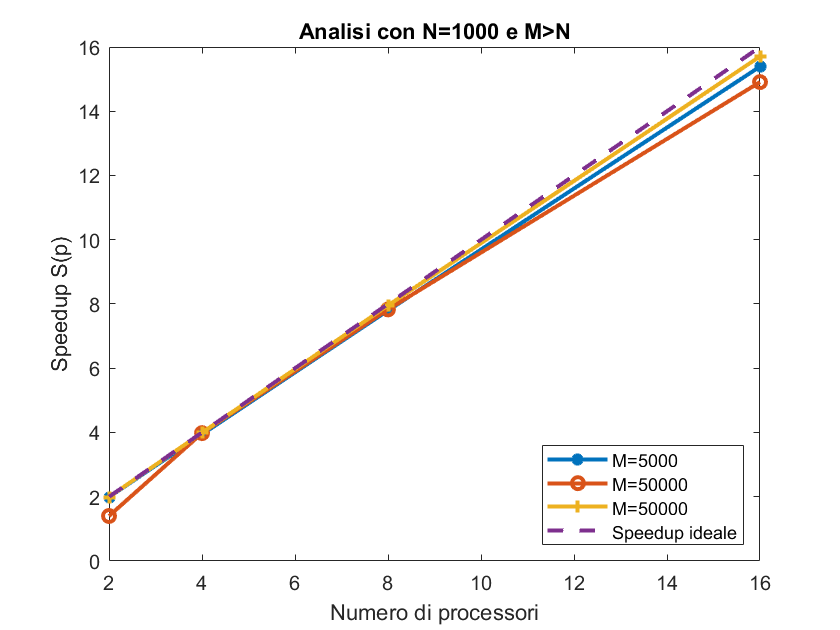

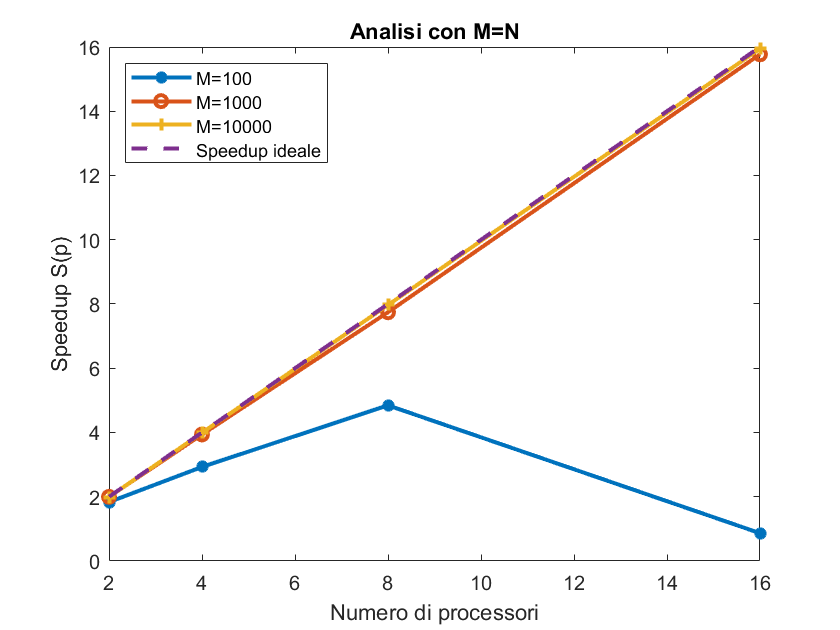

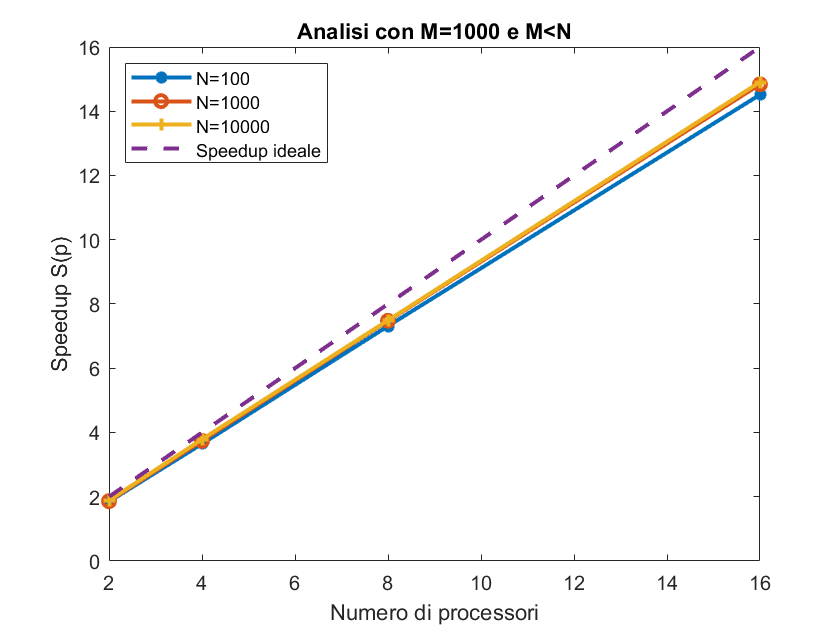

%esecuzione script per tabelle e grafici
speedup

Infine si è calcolata l'efficienza rapportando lo speed-up S(p) al numero di processori p.

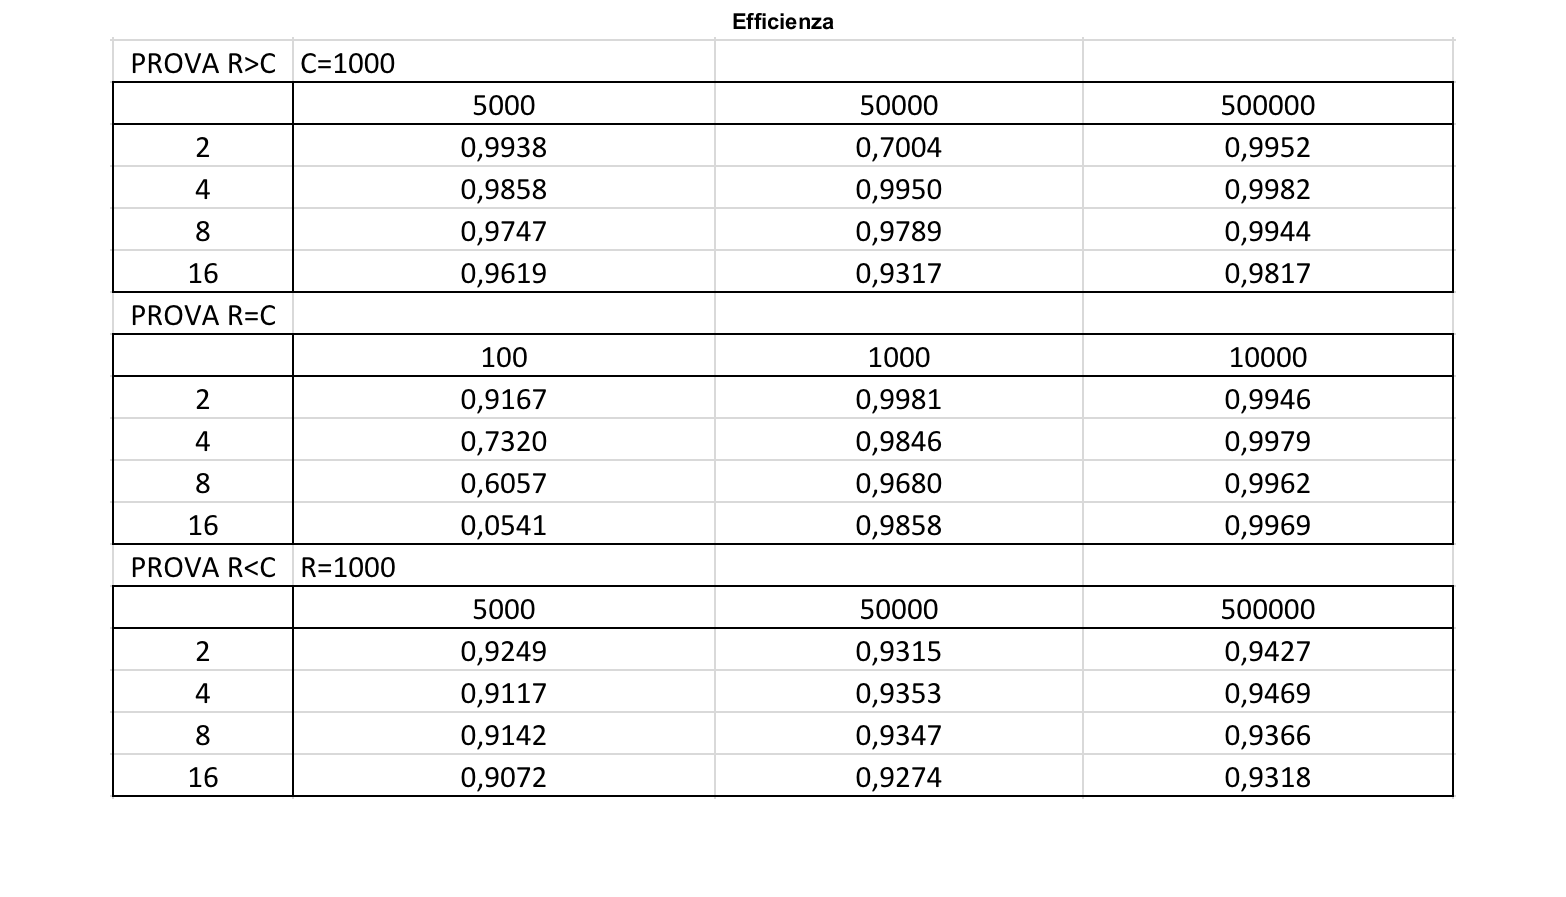

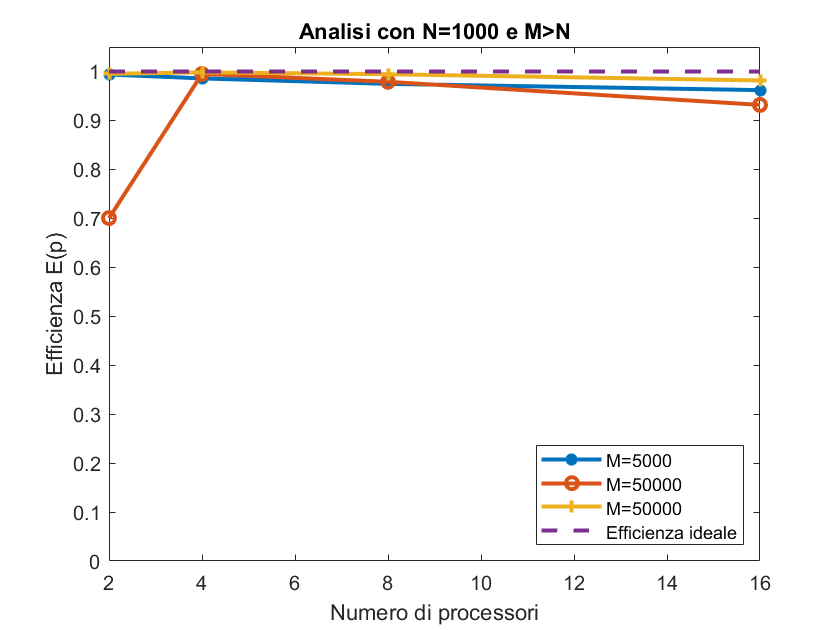

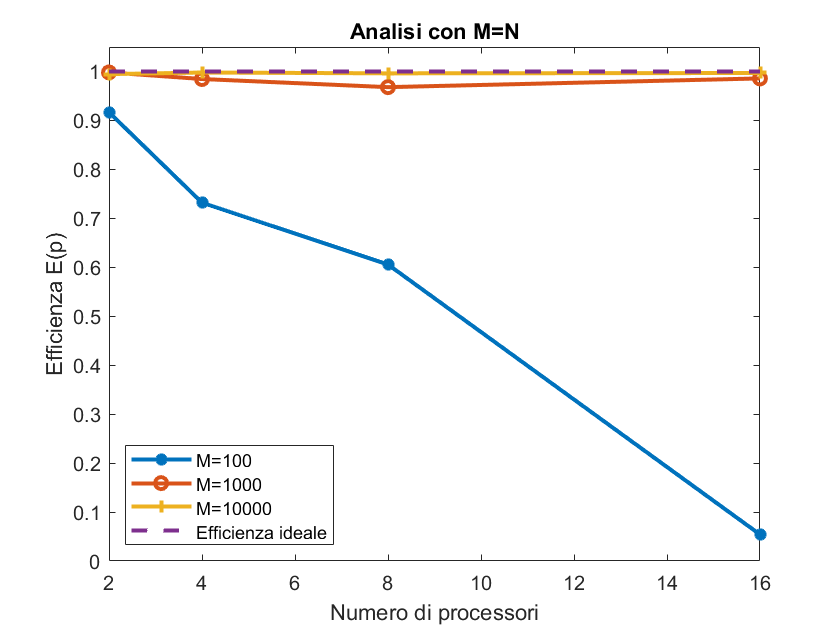

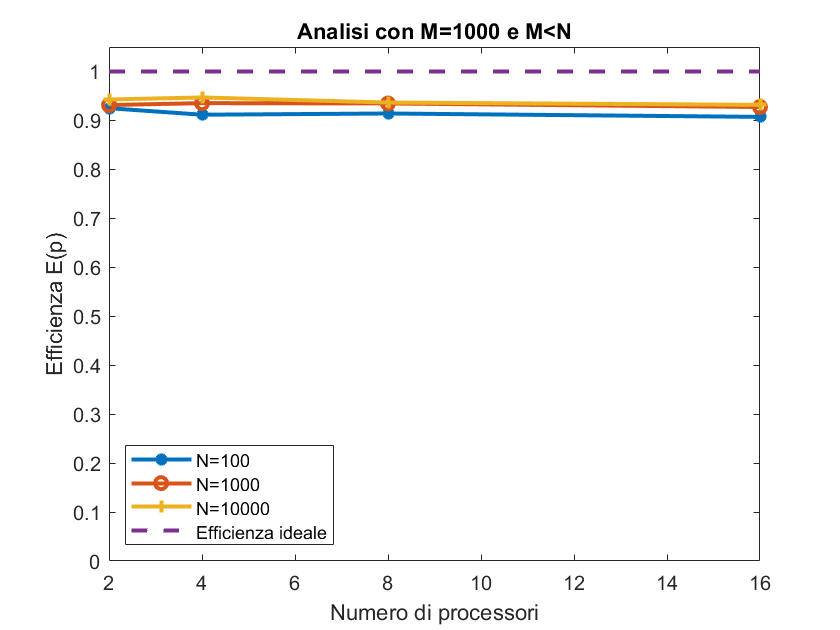

%esecuzione script per tabelle e grafici
efficienza

## Conclusioni

Dai grafici e dalle tabelle appena presentate si possono trarre considerazioni diverse nei tre casi prima citati:

- se M>N o M<N l'efficienza migliore si ha per 2 processori quando M=5000. Se M=50000 o 500000 invece il numero ottimo di processori risulta pari a 4. Tuttavia l'efficienza risulta complessivamente maggiore nella configurazione in cui M>N.

- se M=N l'efficienza migliore si ha per 2 processori per M fino a 1000 mentre è 4 quando M=10000. In particolare si osservi che per M=100 l'efficienza degrada rapidamente all'aumentare del numero di processori date le dimensioni ridotte.

Si possono fare ulteriori considerazioni notando che, per una dimensione fissata, l'efficienza peggiora dopo un certo valore di p (ciò verifica sperimentalmente la legge di Amdahl), e che, in generale, all'aumentare sia della dimensione del problema che di p, l'efficienza migliora o non peggiore come nel caso di M=N (verificando la legge di Gustafson).

Analoghe considerazioni per i tempi e lo speedup.

## ANALISI DELL' ACCURATEZZA

Confrontando il risultato ottenuto sul cluster Scope e quello ottenuto su MATLAB si ottiene il seguente errore relativo (tramite il comando `norm)`, fissando a 4 il numero di processori con dimensione della matrice pari a 7x8.

%esecuzione script per i test di accuratezza
accuratezza

errore_relativo = 4.3402e-06